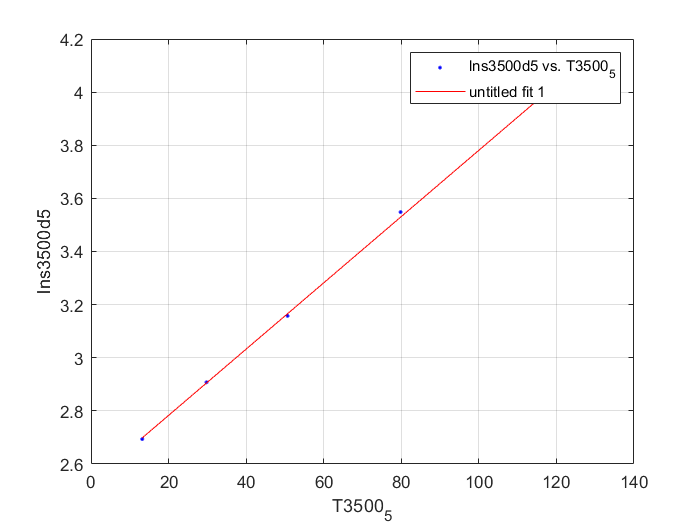

[xData, yData] = prepareCurveData( T3500_5, lns3500d5 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns3500d5 vs. T3500_5', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel T3500_5
ylabel lns3500d5
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01248  (0.01201, 0.01294)
  %     p2 =       2.534  (2.5, 2.567)

%Goodness of fit:
 % SSE: 0.0005283
  %R-square: 0.9996
 % Adjusted R-square: 0.9994
  %RMSE: 0.01327